# Brainwave Analysis

## In this section we are going to explore how we can use the data you collected on your Muse headset to extract meaningful information and implement filters. 

Using the information on the [https://musedirect.choosemuse.com/](https://musedirect.choosemuse.com/) website, I learned that the results from EEG 2 had the highest accuracy, so let's start by plotting that

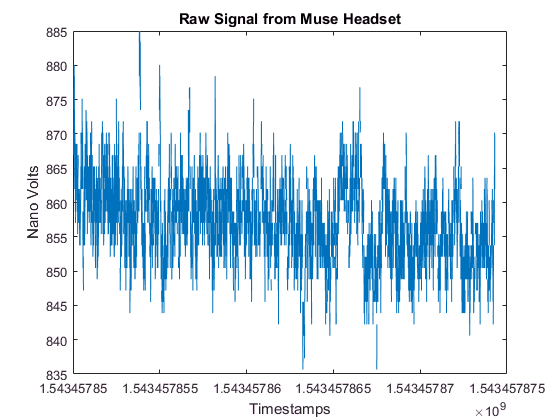

plot(timestamps,eeg_2)
title('Raw Signal from Muse Headset')
xlabel('Timestamps')
ylabel('Nano Volts')

You can see that the plot we have is very rough, and could definitely use some filtering. From this sample I want to get a cleaner line, so I think it's time to implement a moving average filter.

out = zeros(1,length(eeg_2));

for i=2:length(eeg_2)-1
    out(i) = (eeg_2(i-1)+eeg_2(i)+eeg_2(i+1))./3;
end
out;
out = out(2:end);

length(out)

ans = 11132

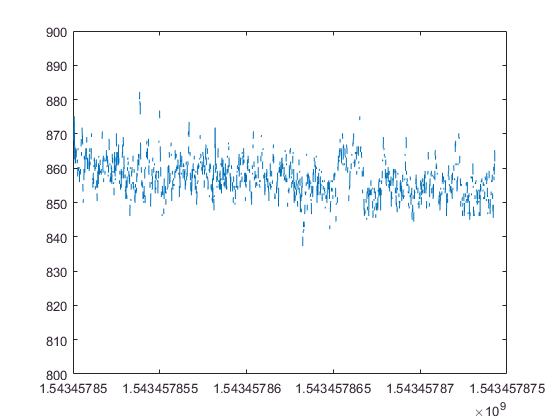

plot(timestamps(1:11132),out)
ylim([800 900])

Now you can see that the signal is definitely less fuzzy, but there is still lots of work to be done. While we got rid of a lot of noise, it is still difficult to identify longer term trends. Previously we implemented a 3 point moving average filter, but notice that the sampling rate of this sensor is extremely high, about 460 datapoints per second. This super high sampling rate is not really useful to us, so lets reduce the number of datapoints we use.

reduced_data = eeg_2(1:10:end,:);
reduced_data = reduced_data(all(~isnan(reduced_data),2),:);

length(reduced_data)

ans = 533

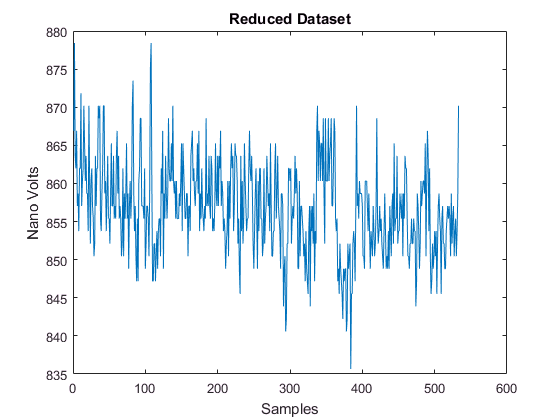

timestamp = linspace(1,533,533);
plot(timestamp, reduced_data)
title('Reduced Dataset')
xlabel('Samples')
ylabel('Nano Volts')

Notice that when we take only 1 every 10th row, we can still see the same general trends, but with less "fuzz". Now lets apply the moving average filter again and see if we can achieve better results.

outnew = zeros(1,length(reduced_data));


for i=2:length(reduced_data)-1
    outnew(i) = (reduced_data(i-1)+reduced_data(i)+reduced_data(i+1))./3;
end
outnew;
length(outnew)

ans = 533

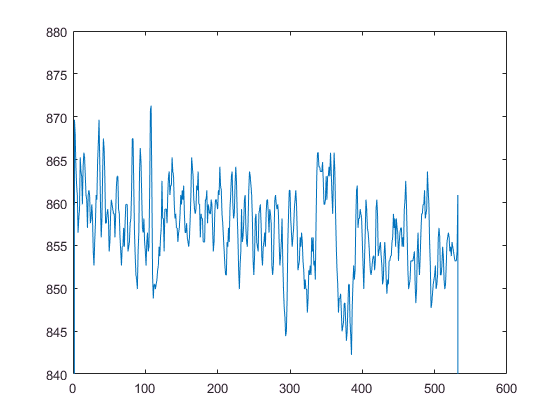

plot(timestamp,outnew)
ylim([840 880])

At this point you might be saying "Wow, look how much cleaner that is", and you'd be right. By using a moving average filter and reducing the sampling rate, we've cleaned up the filter immensely.

windowSize = 20; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

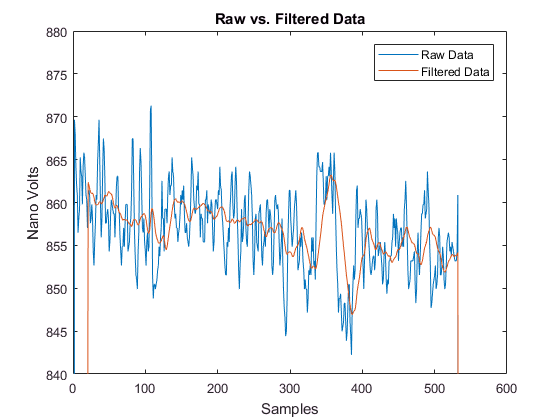

clf
y = filter(b,a,outnew);


plot(timestamp,outnew)
hold on
plot(timestamp,y)
ylim([840 880])
legend('Raw Data','Filtered Data')
title('Raw vs. Filtered Data')
xlabel('Samples')
ylabel('Nano Volts')

clf
y=y(25:515)

y =   861.0924  861.0375  861.1198  860.9279  860.5989  860.1054  859.8038  859.6941  859.7216  859.7490  859.8038  860.0231  860.1054  860.0506  859.8312  859.8861  860.0231  860.3247  860.5989  860.8730  860.8456  860.7360  860.7634  861.0101  861.2843  861.2295  861.1198  861.0101  861.0101  860.7634  860.3795  859.8312  859.5296  859.3377  859.4748  859.6667  859.6393  859.4200  859.0636  858.8442  858.7620  858.5975  858.2959  858.0766  857.9121  858.0492  858.0217  857.9669  857.9395  857.9395


length(y)

ans = 491

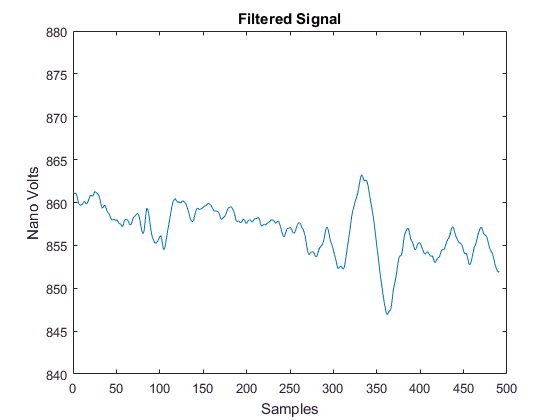

timestampy = linspace(1,491,491);
plot(timestampy,y)
ylim([840 880])
title('Filtered Signal')
xlabel('Samples')
ylabel('Nano Volts')

y = y - mean(y);
freq = fft(y);

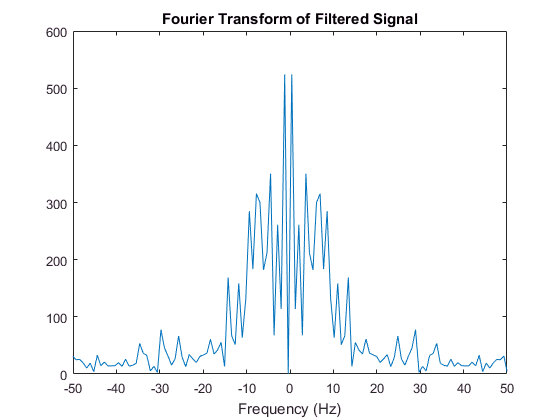

clf
Fs = 400;
FS = linspace(-Fs/2, Fs/2 - Fs/length(y), length(y));
plot(FS, fftshift(abs(freq)))
xlim([-50 50])
title('Fourier Transform of Filtered Signal')
xlabel('Frequency (Hz)')

y1 = y(1:100);
y1 = y1 - mean(y1);
y2 = y(101:200);
y2 = y2 - mean(y2);
y3 = y(201:300);
y3 = y3 - mean(y3);
y4 = y(301:400);
y4 - y4 - mean(y4);
y5 = y(401:491);
y5 = y5 - mean(y5);

fft1 = fft(y1);
fft2 = fft(y2);
fft3 = fft(y3);
fft4 = fft(y4);
fft5 = fft(y5);

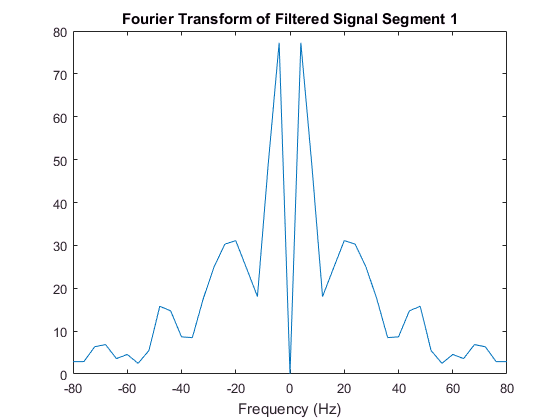

clf
Fs = 400;
FS = linspace(-Fs/2, Fs/2 - Fs/length(y1), length(y1));
plot(FS, fftshift(abs(fft1)))
xlim([-80 80])
title('Fourier Transform of Filtered Signal Segment 1')
xlabel('Frequency (Hz)')

fftpk = fftshift(abs(fft1))

fftpk =     2.8239    2.8213    2.8055    2.9511    2.8519    2.6214    2.7105    2.4402    2.5752    2.3810    2.6716    2.2090    2.9300    2.7596    2.7501    2.7774    2.7881    2.8512    2.9165    2.8712    2.9576    3.0737    3.3577    2.6353    3.6435    3.4935    4.3011    3.3683    4.3031    4.0403    2.8965    2.8807    6.3533    6.8589    3.5938    4.5555    2.4784    5.4878   15.8012   14.7236    8.6570    8.4908   17.5259   24.9808   30.2942   31.1015   24.6226   18.0623   49.1716   77.2458


fftpks = fftpk(51:end)

fftpks =          0   77.2458   49.1716   18.0623   24.6226   31.1015   30.2942   24.9808   17.5259    8.4908    8.6570   14.7236   15.8012    5.4878    2.4784    4.5555    3.5938    6.8589    6.3533    2.8807    2.8965    4.0403    4.3031    3.3683    4.3011    3.4935    3.6435    2.6353    3.3577    3.0737    2.9576    2.8712    2.9165    2.8512    2.7881    2.7774    2.7501    2.7596    2.9300    2.2090    2.6716    2.3810    2.5752    2.4402    2.7105    2.6214    2.8519    2.9511    2.8055    2.8213


FSpks = FS(51:end)

FSpks =      0     4     8    12    16    20    24    28    32    36    40    44    48    52    56    60    64    68    72    76    80    84    88    92    96   100   104   108   112   116   120   124   128   132   136   140   144   148   152   156   160   164   168   172   176   180   184   188   192   196


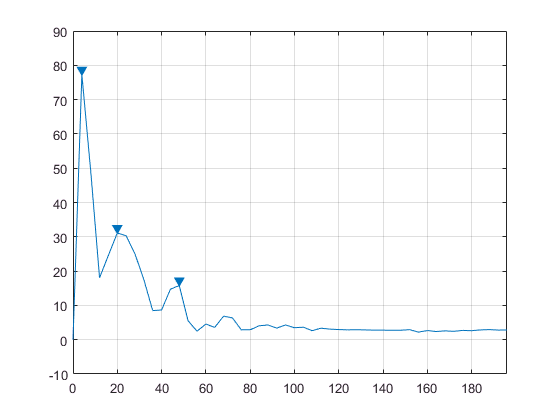

findpeaks(fftpks,FSpks,'MinPeakProminence',7)

[pks,HZ1] = findpeaks(fftpks, FSpks, 'MinPeakProminence',7)

pks =    77.2458   31.1015   15.8012


HZ1 =      4    20    48


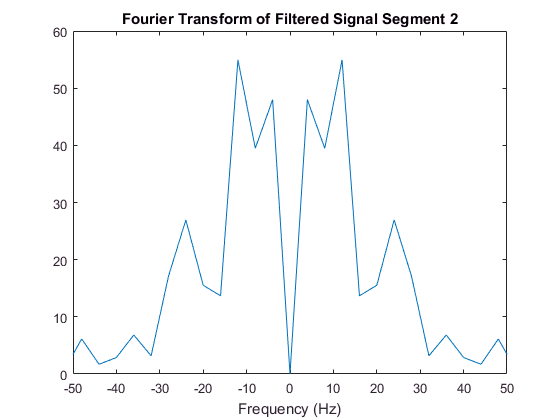

clf
Fs = 400;
FS = linspace(-Fs/2, Fs/2 - Fs/length(y2), length(y2));
plot(FS, fftshift(abs(fft2)))
xlim([-50 50])
title('Fourier Transform of Filtered Signal Segment 2')
xlabel('Frequency (Hz)')

fftpk2 = fftshift(abs(fft2))

fftpk2 =     0.8225    0.9365    0.0990    0.7712    1.1950    0.9822    1.2847    0.8156    0.1944    0.8492    0.6590    0.8290    0.4843    0.7736    0.6791    0.8007    0.7941    0.8287    0.7466    0.8259    0.9505    1.1125    0.7067    1.0651    0.9691    0.6936    0.2542    1.6434    1.6226    0.4383    0.2440    0.7167    0.8014    1.8404    1.4289    0.4420    1.5896    0.7511    6.1299    1.7001    2.8863    6.8250    3.1772   17.0943   26.9490   15.5152   13.6796   54.9548   39.4801   47.9889


fftpks2 = fftpk2(51:end)

fftpks2 =     0.0000   47.9889   39.4801   54.9548   13.6796   15.5152   26.9490   17.0943    3.1772    6.8250    2.8863    1.7001    6.1299    0.7511    1.5896    0.4420    1.4289    1.8404    0.8014    0.7167    0.2440    0.4383    1.6226    1.6434    0.2542    0.6936    0.9691    1.0651    0.7067    1.1125    0.9505    0.8259    0.7466    0.8287    0.7941    0.8007    0.6791    0.7736    0.4843    0.8290    0.6590    0.8492    0.1944    0.8156    1.2847    0.9822    1.1950    0.7712    0.0990    0.9365


FSpks = FS(51:end)

FSpks =      0     4     8    12    16    20    24    28    32    36    40    44    48    52    56    60    64    68    72    76    80    84    88    92    96   100   104   108   112   116   120   124   128   132   136   140   144   148   152   156   160   164   168   172   176   180   184   188   192   196


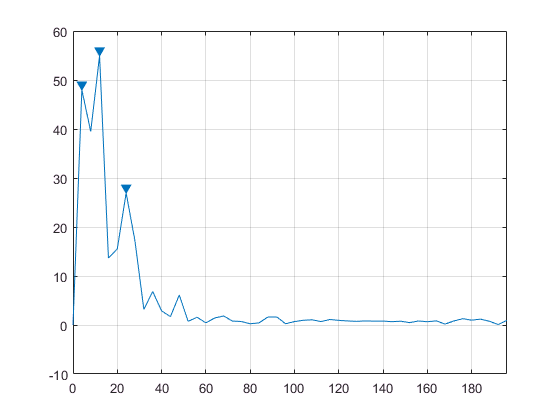

findpeaks(fftpks2,FSpks,'MinPeakProminence',7)

[pks,HZ2] = findpeaks(fftpks2, FSpks, 'MinPeakProminence',7)

pks =    47.9889   54.9548   26.9490


HZ2 =      4    12    24


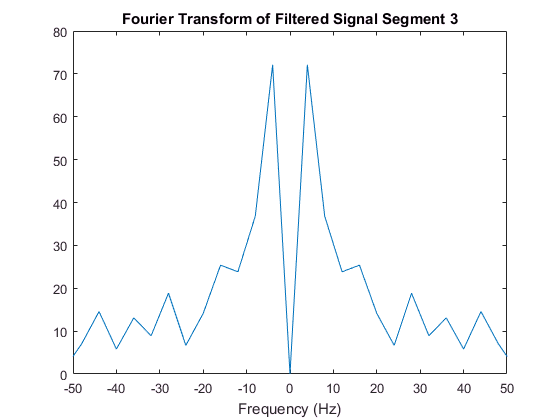

clf
Fs = 400;
FS = linspace(-Fs/2, Fs/2 - Fs/length(y3), length(y3));
plot(FS, fftshift(abs(fft3)))
xlim([-50 50])
title('Fourier Transform of Filtered Signal Segment 3')
xlabel('Frequency (Hz)')

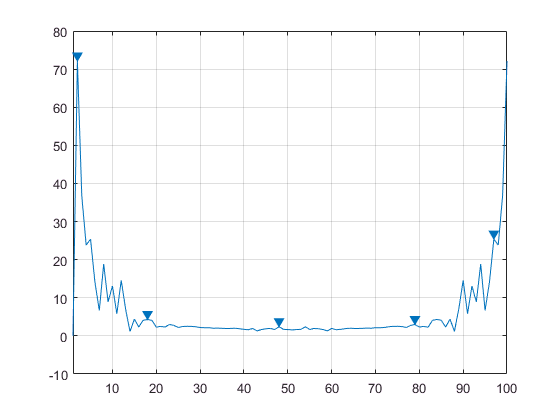

fft3p = abs(fft3);
findpeaks(fft3p, 'MinPeakDistance',15)

[pks,HZ3] = findpeaks(fft3p, 'MinPeakDistance',15)

pks =    72.1160    4.2974    2.3998    2.9859   25.3904


HZ3 =      2    18    48    79    97


fftpk3 = fftshift(abs(fft3))

fftpk3 =     1.5627    1.6633    1.7157    2.3998    1.6698    1.9602    1.8664    1.6753    1.2948    1.9513    1.6155    1.7087    1.8764    2.0155    1.9571    1.9391    1.9831    2.0415    2.0080    2.1508    2.1363    2.2021    2.3948    2.5018    2.5136    2.4511    2.2035    2.7429    2.9859    2.3217    2.4849    2.2819    4.0915    4.2974    4.1021    2.3312    4.3959    1.1738    7.0466   14.5687    5.8063   13.0937    8.9182   18.8471    6.6782   14.1246   25.3904   23.8333   36.7983   72.1160


fftpks3 = fftpk3(51:end)

fftpks3 =     0.0000   72.1160   36.7983   23.8333   25.3904   14.1246    6.6782   18.8471    8.9182   13.0937    5.8063   14.5687    7.0466    1.1738    4.3959    2.3312    4.1021    4.2974    4.0915    2.2819    2.4849    2.3217    2.9859    2.7429    2.2035    2.4511    2.5136    2.5018    2.3948    2.2021    2.1363    2.1508    2.0080    2.0415    1.9831    1.9391    1.9571    2.0155    1.8764    1.7087    1.6155    1.9513    1.2948    1.6753    1.8664    1.9602    1.6698    2.3998    1.7157    1.6633


FSpks = FS(51:end)

FSpks =      0     4     8    12    16    20    24    28    32    36    40    44    48    52    56    60    64    68    72    76    80    84    88    92    96   100   104   108   112   116   120   124   128   132   136   140   144   148   152   156   160   164   168   172   176   180   184   188   192   196


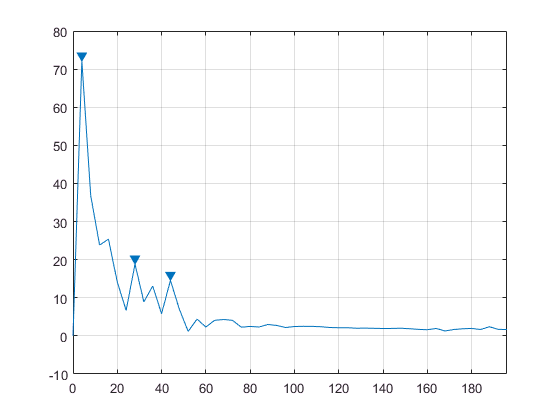

findpeaks(fftpks3,FSpks,'MinPeakProminence',7)

[pks,HZ3] = findpeaks(fftpks3, FSpks, 'MinPeakProminence',7)

pks =    72.1160   18.8471   14.5687


HZ3 =      4    28    44


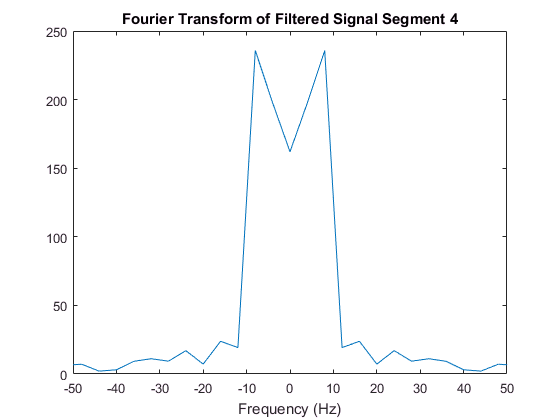

clf
Fs = 400;
FS = linspace(-Fs/2, Fs/2 - Fs/length(y4), length(y4));
plot(FS, fftshift(abs(fft4)))
xlim([-50 50])
title('Fourier Transform of Filtered Signal Segment 4')
xlabel('Frequency (Hz)')

fftpk4 = fftshift(abs(fft4))

fftpk4 =     0.3838    0.8229    0.7273    0.7270    0.1253    0.5562    0.4792    0.8657    0.5611    0.4560    0.5003    0.4593    0.8714    0.3455    0.3446    0.5348    0.5379    0.5431    0.6137    0.6669    0.5910    0.9230    0.8348    1.1124    0.7019    0.8670    0.3037    2.2193    1.4861    0.5956    0.1735    1.1175    4.0769    4.5866    3.1031    0.5810    1.7968    6.3369    7.1301    2.0998    3.0802    9.2426   11.1326    9.3513   17.0182    7.2079   23.8334   19.2549  235.8162  197.6272


fftpks4 = fftpk4(51:end)

fftpks4 =   161.9600  197.6272  235.8162   19.2549   23.8334    7.2079   17.0182    9.3513   11.1326    9.2426    3.0802    2.0998    7.1301    6.3369    1.7968    0.5810    3.1031    4.5866    4.0769    1.1175    0.1735    0.5956    1.4861    2.2193    0.3037    0.8670    0.7019    1.1124    0.8348    0.9230    0.5910    0.6669    0.6137    0.5431    0.5379    0.5348    0.3446    0.3455    0.8714    0.4593    0.5003    0.4560    0.5611    0.8657    0.4792    0.5562    0.1253    0.7270    0.7273    0.8229


FSpks = FS(51:end)

FSpks =      0     4     8    12    16    20    24    28    32    36    40    44    48    52    56    60    64    68    72    76    80    84    88    92    96   100   104   108   112   116   120   124   128   132   136   140   144   148   152   156   160   164   168   172   176   180   184   188   192   196


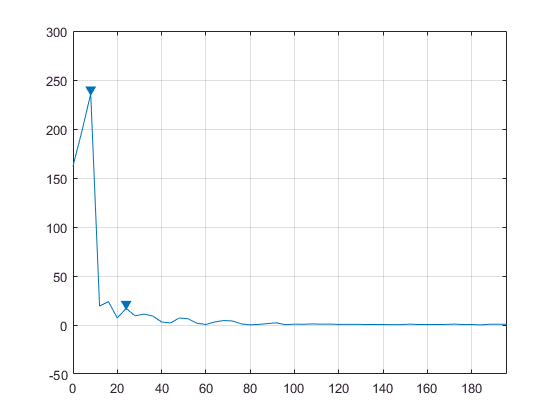

findpeaks(fftpks4,FSpks,'MinPeakProminence',7)

[pks,HZ4] = findpeaks(fftpks4, FSpks, 'MinPeakProminence',7)

pks =   235.8162   17.0182


HZ4 =      8    24


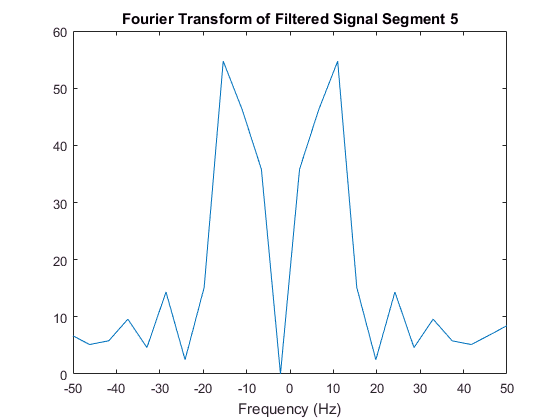

clf
Fs = 400;
FS = linspace(-Fs/2, Fs/2 - Fs/length(y5), length(y5));
plot(FS, fftshift(abs(fft5)))
xlim([-50 50])
title('Fourier Transform of Filtered Signal Segment 5')
xlabel('Frequency (Hz)')

fftpk5 = fftshift(abs(fft5))

fftpk5 =     1.3994    1.5238    1.1747    2.0807    1.6153    1.5786    1.5405    1.6555    1.7515    1.7246    1.7903    1.3557    1.6036    1.6584    1.7376    1.7409    1.8058    1.9731    1.9111    1.9263    1.9207    2.0091    2.0579    2.1573    3.1778    2.7622    2.2217    2.3787    2.3793    6.8767    3.6851    3.4032    2.3523    8.6929    6.8838    5.1551    5.8066    9.5920    4.6157   14.3426    2.4902   15.1453   54.7226   46.1848   35.8179    0.0000   35.8179   46.1848   54.7226   15.1453


fftpks5 = fftpk5(47:end)

fftpks5 =    35.8179   46.1848   54.7226   15.1453    2.4902   14.3426    4.6157    9.5920    5.8066    5.1551    6.8838    8.6929    2.3523    3.4032    3.6851    6.8767    2.3793    2.3787    2.2217    2.7622    3.1778    2.1573    2.0579    2.0091    1.9207    1.9263    1.9111    1.9731    1.8058    1.7409    1.7376    1.6584    1.6036    1.3557    1.7903    1.7246    1.7515    1.6555    1.5405    1.5786    1.6153    2.0807    1.1747    1.5238    1.3994


FSpks = FS(47:end)

FSpks =     2.1978    6.5934   10.9890   15.3846   19.7802   24.1758   28.5714   32.9670   37.3626   41.7582   46.1538   50.5495   54.9451   59.3407   63.7363   68.1319   72.5275   76.9231   81.3187   85.7143   90.1099   94.5055   98.9011  103.2967  107.6923  112.0879  116.4835  120.8791  125.2747  129.6703  134.0659  138.4615  142.8571  147.2527  151.6484  156.0440  160.4396  164.8352  169.2308  173.6264  178.0220  182.4176  186.8132  191.2088  195.6044


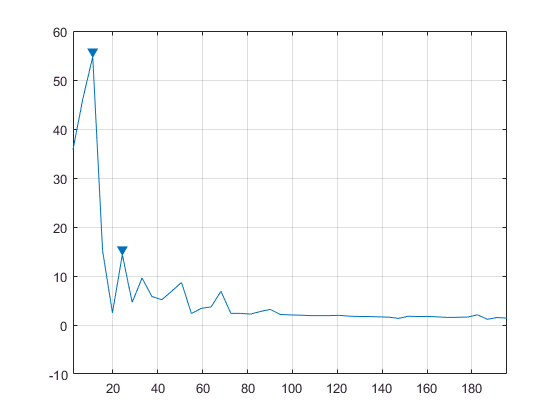

findpeaks(fftpks5,FSpks,'MinPeakProminence',7)

[pks,HZ5] = findpeaks(fftpks5, FSpks, 'MinPeakProminence',7)

pks =    54.7226   14.3426


HZ5 =    10.9890   24.1758


segAmount = 5

segAmount = 5

numbers = linspace(1,100,100)

numbers =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


Gamma = numbers(31:100)

Gamma =     31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80


Beta = numbers(13:32)

Beta =     13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


Alpha = numbers(8:12)

Alpha =      8     9    10    11    12


Theta = numbers(5:8)

Theta =      5     6     7     8


HZ =     4.0000   20.0000   48.0000    4.0000   12.0000   24.0000    4.0000   28.0000   44.0000    8.0000   24.0000   10.9890   24.1758


HZlengths =      3     3     3     2     2


value1 = assement(HZ1)

n =     20    48


Session = 'Beta'

values = 3

segmentvalue = 3

Session = 'Gamma'

values =      3     4


segmentvalue = 3.5000

value1 = 3.5000

value2 = assement(HZ2)

n =     12    24


Session = 'Alpha'

values = 2

segmentvalue = 2

Session = 'Beta'

values =      2     3


segmentvalue = 2.5000

value2 = 2.5000

value3 = assement(HZ3)

n =     28    44


Session = 'Beta'

values = 3

segmentvalue = 3

Session = 'Gamma'

values =      3     4


segmentvalue = 3.5000

value3 = 3.5000

value4 = assement(HZ4)

n =      8    24


Session = 'Alpha'

values = 2

Session = 'Theta'

values = 1

segmentvalue = 1

Session = 'Beta'

values =      1     3


segmentvalue = 2

value4 = 2

value5 = assement(HZ5)

FullSession = [value1 value2 value3 value4 value5]

FullSession =     3.5000    2.5000    3.5000    2.0000    2.5000


meditationLine = ones(1,length(FullSession))*3

meditationLine =      3     3     3     3     3


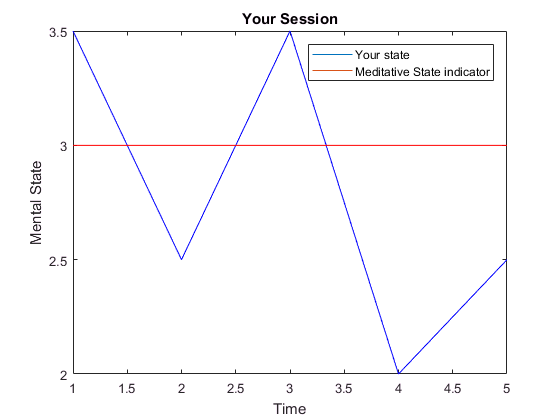

plot(FullSession, 'b')
hold on
plot(meditationLine, 'r')
title('Your Session')
legend('Your state', 'Meditative State indicator')
xlabel('Time')
ylabel('Mental State')

function segmentvalue = assement(n)
numbers = linspace(1,100,100);
Gamma = numbers(31:100);
Beta = numbers(13:32);
Alpha = numbers(8:12);
Theta = numbers(5:8);
values = [];
n = n(n>4)
n = [fix(n)]
        for i = 1:length(n)
            if ismember(n(i), Gamma) == 1
                Session = ['Gamma']
                values(i) = [4]
            end
            if ismember(n(i), Beta) == 1
                Session = ['Beta']
                values(i) = [3]
            end
            if ismember(n(i), Alpha) == 1
                Session = ['Alpha']
                values(i) = [2]
            end
            if ismember(n(i), Theta) == 1
                Session = ['Theta']
                values(i) = [1]
            end
            segmentvalue = sum(values)/length(values)
        end
end



    
            
                
